clc; 
clear all; 
close all;

## loading data

train_data = loadMNISTImages('train-images.idx3-ubyte'); 
train_label = loadMNISTLabels('train-labels.idx1-ubyte'); 
test_data = loadMNISTImages('t10k-images.idx3-ubyte'); 
test_label = loadMNISTLabels('t10k-labels.idx1-ubyte');

train_cell = cell(1,10);
for i = 1 : size(train_data, 2) %put in data matrix
    label = train_label(i,:);
    train_cell{label+1} = [train_cell{label+1} train_data(:,i)];
end

## Center the input data

for i = 1:10
   temp_mean(:,i) = mean(train_cell{i},2);
   train_cell{i} = train_cell{i} - temp_mean(:,i);
end

## Initialize the weights W (i)and σ (i)s randomly.

K1 = 50; % K = [50,100]
K2 = 100;
D = size(train_data, 1);
W_50 = rand(size(train_data,1), K1); %Initialize the weights W (i)and σ (i)s randomly.
W_100 = rand(size(train_data,1), K2);
sigma = rand();

## for K= 50

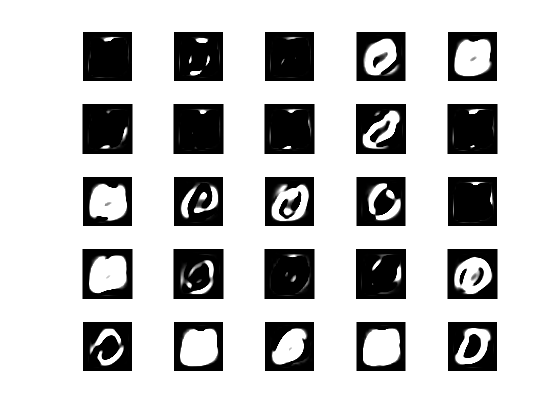

Completed digit: 0


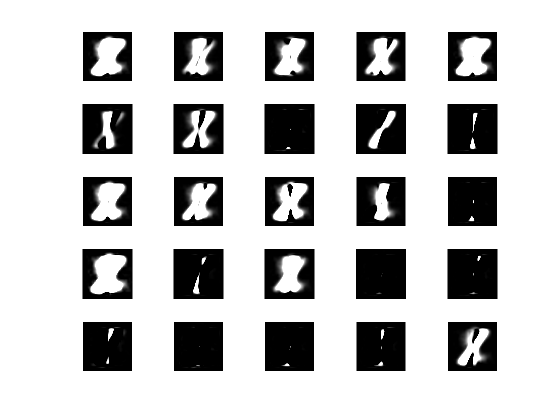

Completed digit: 1


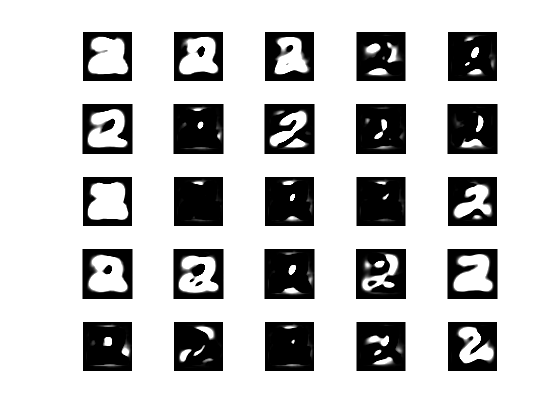

Completed digit: 2


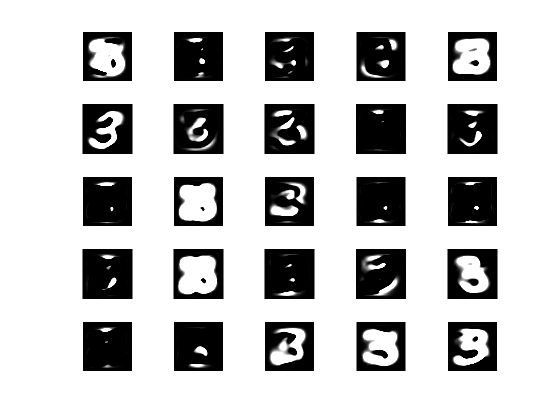

Completed digit: 3


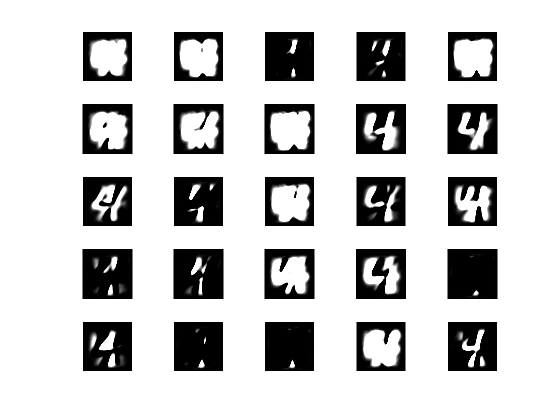

Completed digit: 4


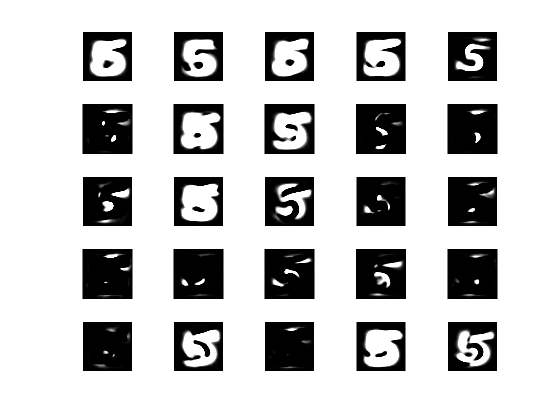

Completed digit: 5


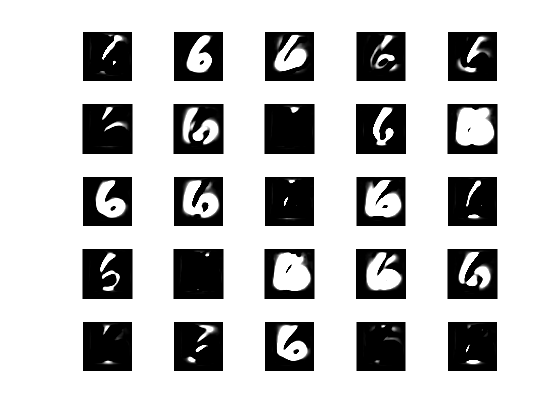

Completed digit: 6


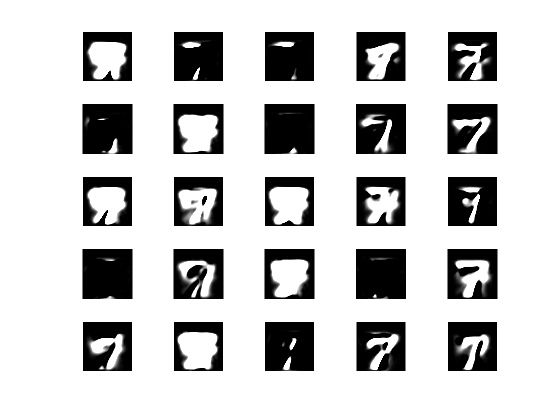

Completed digit: 7


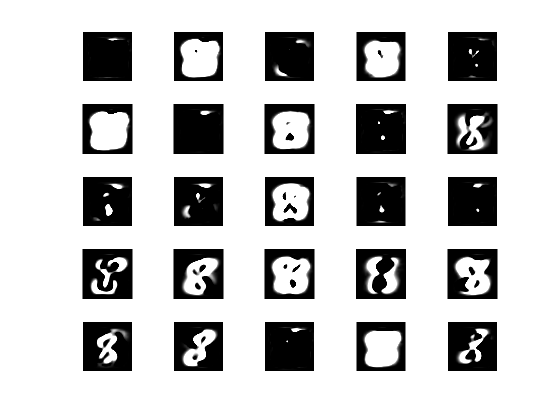

Completed digit: 8


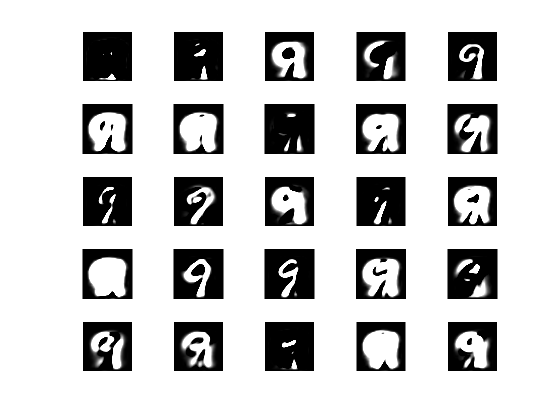

Completed digit: 9


Newdigit_50 = cell(1,10);%new image matrix
% build the new digital use EM function
[Newdigit_50{1}, sigma_square50_0, log_likelihood50_0, diff50_0, count50_0] = EMAlgorithm(train_cell{1}, W_50, sigma, K1);

[Newdigit_50{2}, sigma_square50_1, log_likelihood50_1, diff50_1, count50_1] = EMAlgorithm(train_cell{2}, W_50, sigma, K1);

[Newdigit_50{3}, sigma_square50_2, log_likelihood50_2, diff50_2, count50_2] = EMAlgorithm(train_cell{3}, W_50, sigma, K1);

[Newdigit_50{4}, sigma_square50_3, log_likelihood50_3, diff50_3, count50_3] = EMAlgorithm(train_cell{4}, W_50, sigma, K1);

[Newdigit_50{5}, sigma_square50_4, log_likelihood50_4, diff50_4, count50_4] = EMAlgorithm(train_cell{5}, W_50, sigma, K1);

[Newdigit_50{6}, sigma_square50_5, log_likelihood50_5, diff50_5, count50_5] = EMAlgorithm(train_cell{6}, W_50, sigma, K1);

[Newdigit_50{7}, sigma_square50_6, log_likelihood50_6, diff50_6, count50_6] = EMAlgorithm(train_cell{7}, W_50, sigma, K1);

[Newdigit_50{8}, sigma_square50_7, log_likelihood50_7, diff50_7, count50_7] = EMAlgorithm(train_cell{8}, W_50, sigma, K1);

[Newdigit_50{9}, sigma_square50_8, log_likelihood50_8, diff50_8, count50_8] = EMAlgorithm(train_cell{9}, W_50, sigma, K1);

[Newdigit_50{10}, sigma_square50_9, log_likelihood50_9, diff50_9, count50_9] = EMAlgorithm(train_cell{10}, W_50, sigma, K1);

%plot
for j = 1:10
W = Newdigit_50{j};
figure(j+10);
    for h=1:25
    zn = randn(K1,1);
    Xnew = W*zn + temp_mean(:,j); 
    Image = reshape(Xnew,28,28);
    subplot(5,5,h);
    montage(reshape(Xnew,28,28));
    end
drawnow
disp("Completed digit: " + num2str(j-1));
end

## for K = 100

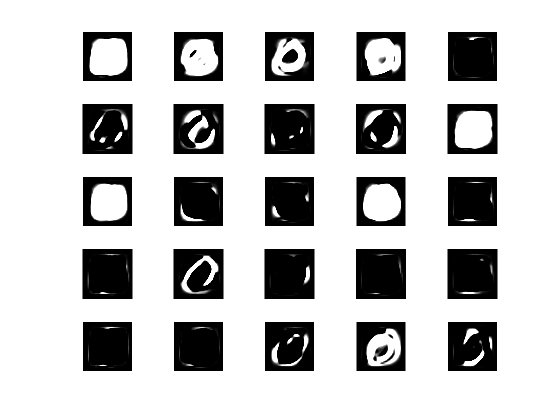

Completed digit: 0


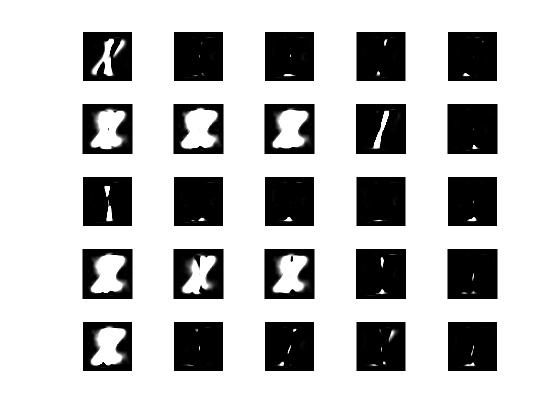

Completed digit: 1


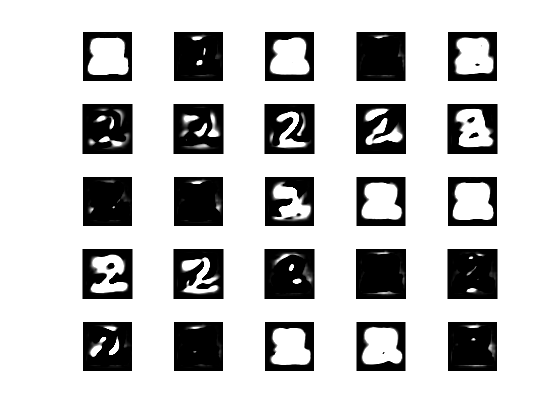

Completed digit: 2


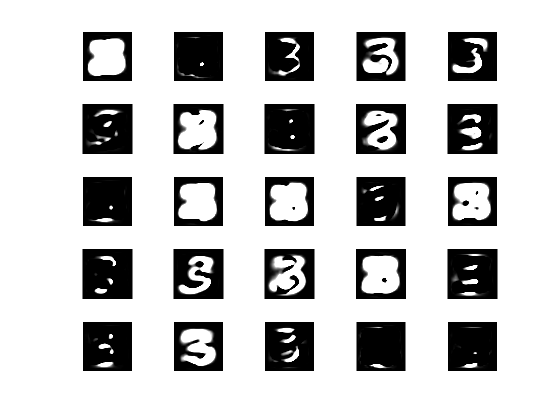

Completed digit: 3


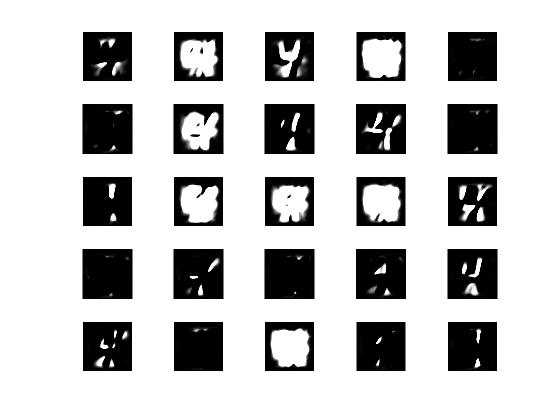

Completed digit: 4


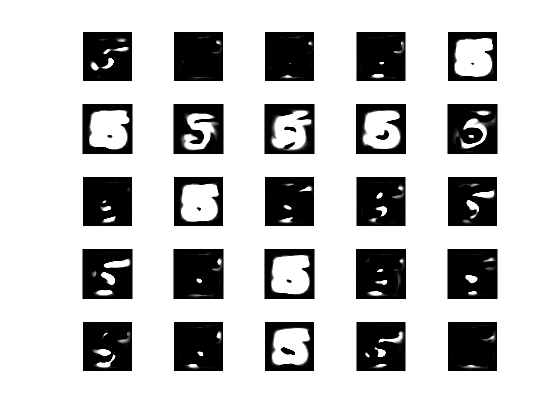

Completed digit: 5


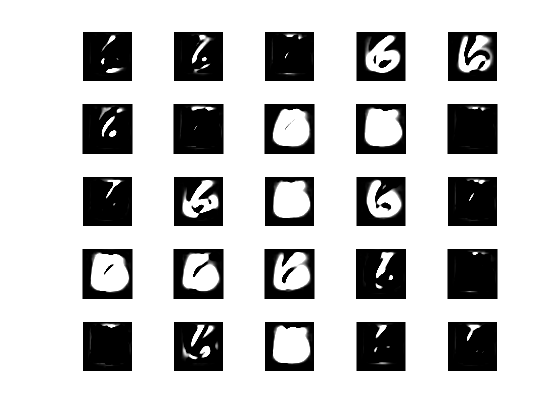

Completed digit: 6


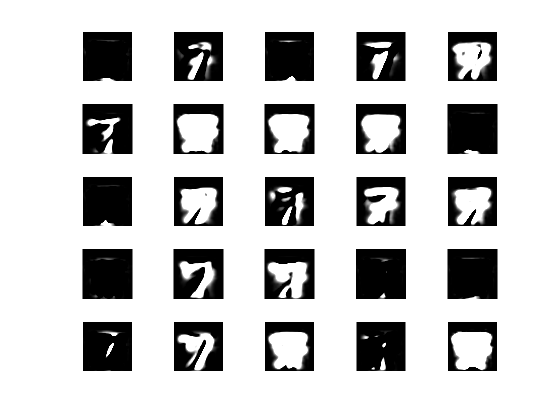

Completed digit: 7


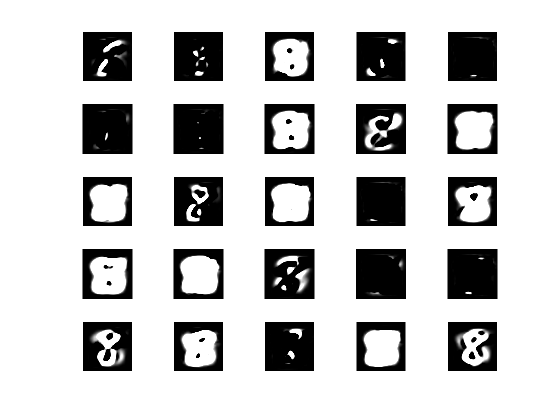

Completed digit: 8


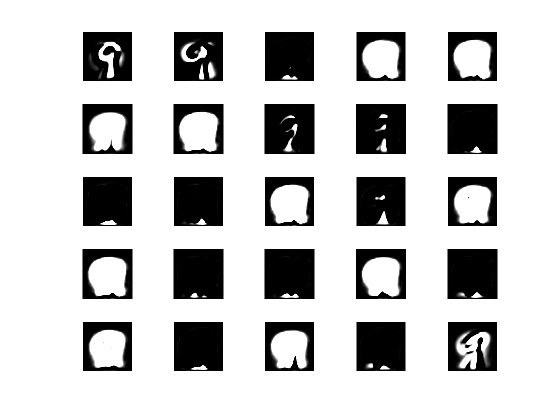

Completed digit: 9


Newdigit_100 = cell(1,10);
%same steps as above
[Newdigit_100{1}, sigma_square_0, log_likelihood_0, diff_0, count_0] = EMAlgorithm(train_cell{1}, W_100, sigma, K2);

[Newdigit_100{2}, sigma_square_1, log_likelihood_1, diff_1, count_1] = EMAlgorithm(train_cell{2}, W_100, sigma, K2);

[Newdigit_100{3}, sigma_square_2, log_likelihood_2, diff_2, count_2] = EMAlgorithm(train_cell{3}, W_100, sigma, K2);

[Newdigit_100{4}, sigma_square_3, log_likelihood_3, diff_3, count_3] = EMAlgorithm(train_cell{4}, W_100, sigma, K2);

[Newdigit_100{5}, sigma_square_4, log_likelihood_4, diff_4, count_4] = EMAlgorithm(train_cell{5}, W_100, sigma, K2);

[Newdigit_100{6}, sigma_square_5, log_likelihood_5, diff_5, count_5] = EMAlgorithm(train_cell{6}, W_100, sigma, K2);

[Newdigit_100{7}, sigma_square_6, log_likelihood_6, diff_6, count_6] = EMAlgorithm(train_cell{7}, W_100, sigma, K2);

[Newdigit_100{8}, sigma_square7, log_likelihood_7, diff_7, count_7] = EMAlgorithm(train_cell{8}, W_100, sigma, K2);

[Newdigit_100{9}, sigma_square8, log_likelihood_8, diff_8, count_8] = EMAlgorithm(train_cell{9}, W_100, sigma, K2);

[Newdigit_100{10}, sigma_square9, log_likelihood_9, diff_9, count_9] = EMAlgorithm(train_cell{10}, W_100, sigma, K2);

%plot
for j = 1:10
W = Newdigit_100{j};
figure(j+10);
    for h=1:25
    zn = randn(K2,1);
    Xnew = W*zn + temp_mean(:,j); 
    Image = reshape(Xnew,28,28);
    subplot(5,5,h);
    montage(reshape(Xnew,28,28))
    end
drawnow
disp("Completed digit: " + num2str(j-1));
end

## EM function

function [W, sigma, liklihood_p, diff, count] = EMAlgorithm(train_data, W, sigma, K)
% the em Algorithm
D = size(train_data, 1);
prob_log = 0;
Identity_matrix = eye(K);
count = 0;

while count < 30 %if you want, change the iter_num here. Higher iter get better graph
    % E-step
    M = W'*W+sigma*Identity_matrix;
    U = chol(M);
    V = inv(U);
    M_inverse = V*V';

    % calculating ln(M)
    ln_M = 2*sum(log(diag(U))) + (D-K)*log(sigma);

    % calculating T
    T = inv(U')*W'*train_data; %k*n

    % sample covariance S
    S = trace(train_data'*train_data);
 
    sum_T_ij = sum(sum(T.^2));
    tri_SinvM= (S - sum_T_ij)/(sigma*size(train_data,2));
    % log liklihood
    liklihood_p = -size(train_data,2)/2*(D*log(2*pi)+ln_M+tri_SinvM);
       
    Mean_Zn = M_inverse*W'*train_data; % k*n
    
    % skip the while loop
    diff = abs(prob_log-liklihood_p);
    prob_log = liklihood_p;
    
    % M-step
    sum_E_Zn_Zn_T = size(train_data,2)*sigma*M_inverse + Mean_Zn*Mean_Zn';
    W_new = (train_data*Mean_Zn')*pinv(sum_E_Zn_Zn_T); % D*K
      
    sigma_new = (1/(size(train_data,2)*D))*(trace(train_data'*train_data)-2*trace(Mean_Zn'*W_new'*train_data)+trace(sum_E_Zn_Zn_T*W_new'*W_new));
    W = W_new; %new weight
    sigma = sigma_new;    
    count = count + 1;

end

end